# Speech in speech-shaped noise (SSN) 

G.FG 2022 (adapted demo scripts from T.H)

% Files and dirs
clear all
addpath('C:\Program Files\MATLAB\R2021a\toolbox\MATLAB_TSM-Toolbox_2.03')
addpath('C:\Users\gfraga\scripts_neulin\Noise_generator\functions')
dirinput = 'C:\Users\gfraga\scripts_neulin\Noise_generator\';
cd(dirinput)


## Inputs 

### File to generate noise from and to embed in noise

wavfileinput = 'MAX00043.wav';
if isempty(wavfileinput)
   wavfileinput = uigetfile('*.wav')
end

if isempty(wavfileinput)
    disp('Specify or browse for input file')
else 
    
    disp(['Using input signal from ', wavfileinput])
end

Using input signal from MAX00043.wav



[S,fsS] = audioread(join([dirinput wavfileinput]));


### Parameters

FFT widows size and 1/n octave band smoothing (spectral smoothing in which the bandwidth of the smoothing window is a constant percentage of the center frequency).

        Nfft = 1000; 
        nOctaves = 6;   % 1/6 octave band smoothing (spectral smoothing in which the bandwidth of the smoothing window is a constant percentage of the center frequency).
        OctaveBandSpace = 1/nOctaves; 

## Filter original signal

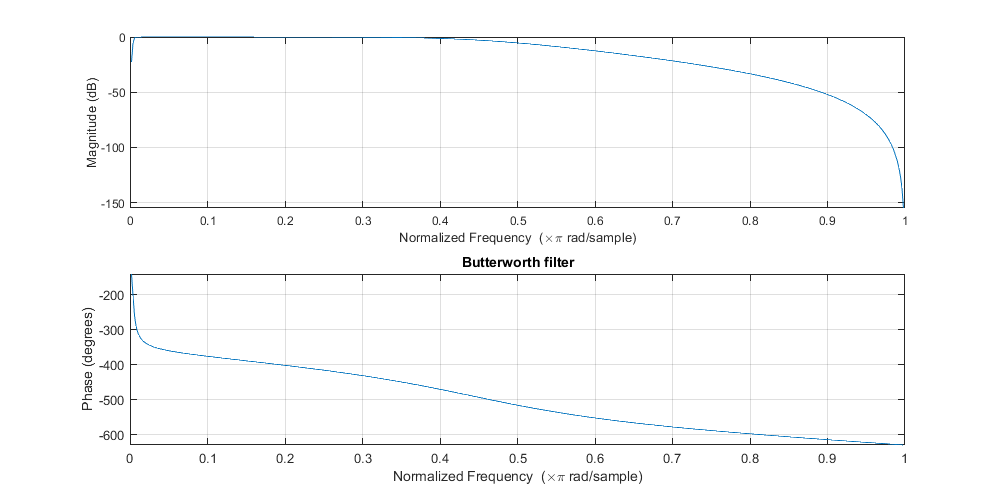

    NyqFreq = fsS/2;            % fs = 2kHz; Nyquist freq. = 1 kHz
    Wn = [50 5000]/NyqFreq;     % Normalised band-pass cut-off frequencies (50-5000Hz)
    [b,a] = butter(6/2,Wn);     % create foreward and backward filter; 6th order            % requires the Signal Processing Toolbox
    S_filt = filtfilt(b,a,S);   % use fvtool(b,a) if you want to visualise the filter
        
  freqz(b,a); title('Butterworth filter');set(gcf,'position',[1 10 1000 500])

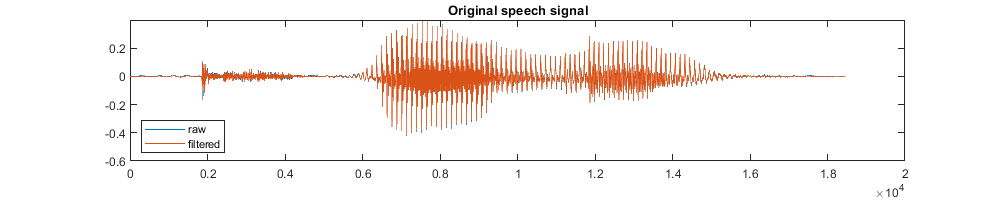

  figure ('Position',[1 10 1000 200])
                plot(S); hold on; plot(S_filt);
                title('Original speech signal');
                legend({'raw', 'filtered'}, 'Location', 'SW');

## Generate white noise 

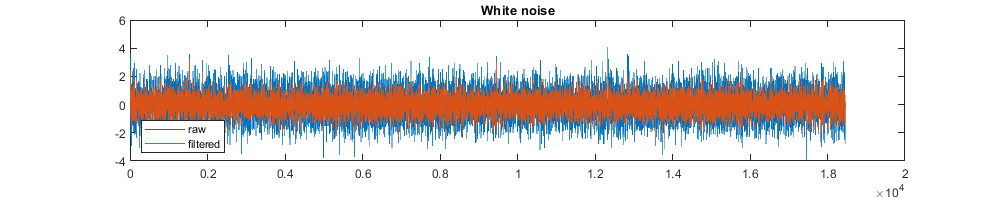

    rng('default');
    whiteNoise = randn(1,length(S_filt));
    whiteNoise_filt = filtfilt(b,a,whiteNoise);
 
      
    figure ('Position',[1 10 1000 200])
    plot(whiteNoise); hold on; plot(whiteNoise_filt);
    title('White noise');
    legend({'raw', 'filtered'}, 'Location', 'SW');

## Speech-Shaped Noise (SSN)

SSN can be obtained by convolving the waveform of speech with the waveform of white noise (time domain) or by multiplying their spectra (frequency domain). The resulting signal will preserve the power spectra of speech. Most commoly, power will be highest around ~400Hz (log scale). This way, noise will mask speech in a way that reflects its spectral distribution of power. One thing to consider is whether to generate individual maskers for each stimulus by convolving it with WN, or to create a common masker, e.g., based on the mean PSD over stimuli. In the former condition, every stimulus will be 'perfectly' masked, but it will be more problematic to compare across the (different) noise conditions, and vice versa.

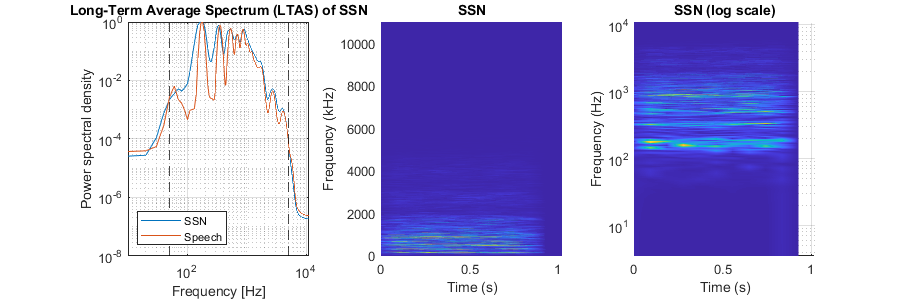


warning('off')
[spect, frqs] = Tools.LTASS(S_filt, Nfft, fsS );        %Compute LTASS spectrum 
SSN = Tools.ArbitraryOctaveFilt(whiteNoise_filt, spect, frqs, Nfft, fsS, OctaveBandSpace);   % Generate Speech shaped noise        
  
figure ('position', [1 10 900 300]);
% LTAS:
subplot(1,3,1);
iosr.dsp.ltas(SSN,fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10);  % requires the IoSR Matlab Toolbox
hold on; iosr.dsp.ltas(S_filt,fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10);
xline(50, '--k'); xline(5000, '--k'); hold off;
title('Long-Term Average Spectrum (LTAS) of SSN');
legend({'SSN', 'Speech'}, 'Location', 'SW');

% Spectrogram
parameter = [];
parameter.fsAudio = fsS;
parameter.zeroPad = fsS/10;
[spec_SSN,f,t] = stft(SSN',parameter);              % requires the MATLAB_TSM-Toolbox_2.02 !

subplot(1,3,2);
surf(t,f,abs(spec_SSN)); hold on; set(gcf,'renderer','zbuffer');
shading interp; axis tight;view(0,90);
title('SSN');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
zlabel('Power (a.u.)');
view(0,90);

subplot(1,3,3);
surf(t,f,abs(spec_SSN)); hold on; set(gcf,'renderer','zbuffer');
set(gca,'zscale','log');  set(gca,'yscale','log');
shading interp; axis tight;view(0,90);
title('SSN (log scale)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
zlabel('Power (a.u.)');

## Speech in Speech-Shaped Noise (SiSSN)

### Normalization 

 RMS_N = rms(SSN);
 RMS_S = rms(S_filt);
 ScaleFact = RMS_N./RMS_N;
 SSN = SSN./ScaleFact;

% now we add up S & N and we equalize the rms of the SiN snippets
target_dB_SNR = -10:5:10;
target_lin_SNR = 10.^(target_dB_SNR/20);

### Signal-to-noise ratio 

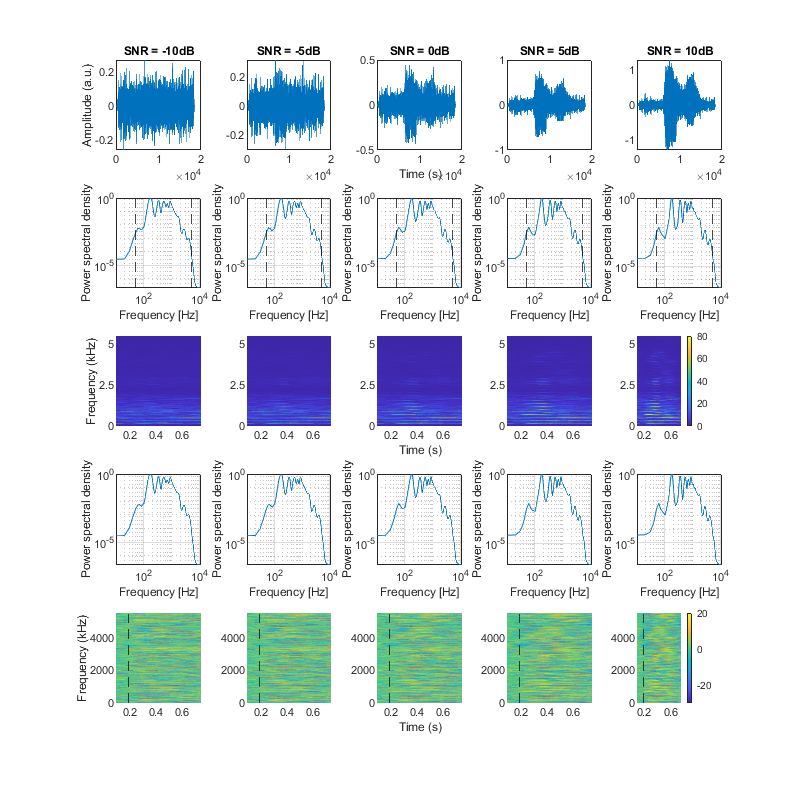

%for i = 1:length(brks)-1
 %   RMS_S = rms(sent_filt{i});
    actual_dB_SNR = 20*log10(RMS_S/RMS_N);
    actual_lin_SNR = 10^(actual_dB_SNR/20);
    for j = 1:length(target_dB_SNR)
        scaleFact_S = target_lin_SNR(j)/actual_lin_SNR;  
        scaled_S{:,j} = S_filt * scaleFact_S;
        SiSSN{:,j} = SSN' + scaled_S{:,j};
        SiSSN_scaled{:,j} = SiSSN{:,j} ./ (rms(SiSSN{:,j})./new_RMS_N);
        % add ramps (10ms) to avoid annoying auditory glitches
        SiSSN{:,j}(1:fsS/100) = SiSSN{:,j}(1:fsS/100) .* linspace(0,1,fsS/100)';
        SiSSN{:,j}(end-fsS/100+1:end) = SiSSN{:,j}(end-fsS/100+1:end) .* linspace(1,0,fsS/100)';
        SiSSN_scaled{:,j}(1:fsS/100) = SiSSN_scaled{:,j}(1:fsS/100) .* linspace(0,1,fsS/100)';
        SiSSN_scaled{:,j}(end-fsS/100+1:end) = SiSSN_scaled{:,j}(end-fsS/100+1:end) .* linspace(1,0,fsS/100)';
    end 

figure ('position', [1 1 800 800]);
row = 1;            % waveform:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(5,5,p);
    plot(SiSSN{1,j});
    %xlim([0 fsS*7]);
    %xticks(0:fsS:fsS*7);
    %xticklabels(0:7);
    %xtickangle(45);
    %ylim([-0.5 0.5]);
    title(['SNR = ' num2str(target_dB_SNR(j)) 'dB']);
    if j == 1
        ylabel('Amplitude (a.u.)');
    end
    if j == 3
        xlabel('Time (s)');
    end
end

noct = 6;
row = 2;            % LTAS:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(5,5,p);
    iosr.dsp.ltas(SiSSN{1,j},fsS,'noct',noct,'graph',true,'units','none','scaling','max0','win',fsS/10);  % requires the IoSR Matlab Toolbox
    hold on;
    xline(50, '--k'); xline(5000, '--k'); hold off;
    
end

row = 3;            % Spectrogram:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    parameter = [];
    parameter.fsAudio = fsS;
    parameter.zeroPad = fsS/10;
    [spec_SiSSN,f,t] = stft(SiSSN{j},parameter);

    subplot(5,5,p);
    surf(t(2:end-3),f(1:round(length(f)/2)+1),abs(spec_SiSSN(1:round(length(f)/2)+1,2:end-3)));
    hold on; set(gcf,'renderer','zbuffer');
    shading interp; view(0,90); axis tight;
    yticks([0 2500 5000]);
    yticklabels(yticks/1000);
   if j == 1
        ylabel('Frequency (kHz)')
    end
    if j == 3
        xlabel('Time (s)');
    end
    if j == 5
        colorbar;
    end
    caxis manual;
    caxis([0 80]);
end


row = 4;   % LTAS normalized:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(5,5,p);
      iosr.dsp.ltas(SiSSN{1,j},fsS,'noct',noct,'graph',true,'units','none','scaling','max0','win',fsS/10);  % requires the IoSR Matlab Toolbox
end


row = 5;            % Spectrogram normalized:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    parameter = [];
    parameter.fsAudio = fsS;
    parameter.zeroPad = fsS/10;
    [spec_SiSSN,f,t] = stft(SiSSN{1,j},parameter);
    
    basl_IDX = 2:3;
    baseline = mean(abs(spec_SiSSN(:,basl_IDX)),2);
    dB_pow = 10*log10(abs(spec_SiSSN)./baseline);
    
    subplot(5,5,p);
    surf(t(2:end-3),f(1:round(length(f)/2)+1),dB_pow(1:round(length(f)/2)+1,2:end-3));
    hold on; set(gcf,'renderer','zbuffer');
    shading interp; view(0,90); axis tight;
    xline(t(basl_IDX(end)), '--k');
    %yticks([0 2500 5000]);
    %yticklabels(yticks/1000);
    if j == 1
        ylabel('Frequency (kHz)')
    end
    if j == 3
        xlabel('Time (s)');
    end
    if j == 5
        colorbar;
    end
    caxis manual;
    caxis([-30 20]);
    
end

    %cb.position(2)=gca.Position(2)

%subtitle('Speech in Speech-Shaped Noise');

## Play sounds

At your own risk! Check your volume settings! 

enableSound = true;
if enableSound== true
      sound(S,fsS);
end

if enableSound== true    
 sound(whiteNoise_filt/500,fsS);  
end

if enableSound==true   
 sound(SSN,fsS);
end

if enableSound==true  
 sound(SiSSN{1},fsS);
end 